clear all
biomass_at800;


R(1:176)=0.0;
plot_biomass(1:176)=0.0;
n(1:176)=0;
for x=1:352
    for y=1:352
        biomass=biomass_800_0(x,y);
        Rcurrent=sqrt((x-176)^2+(y-176)^2);
        for r=1:176
           if Rcurrent>r-1 && Rcurrent <=r
               plot_biomass(r)=plot_biomass(r)+biomass;
               n(r)=n(r)+1;
           end
        end
    end
end
for r=1:176
    if n(r)>0
        plot_biomass(r)=plot_biomass(r)/n(r);
        plot_biomass_left(177-r)=plot_biomass(r);
    end
end


%plot_biomass=biomass_8000_0(:,:)+biomass_8000_1(:,:);
%colororder({'k','y'})

p1=plot([0:175]/100,plot_biomass(:)/1e-4,'k')

p1 =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 … ]
              YData: [0.0011 0.0011 0.0011 0.0011 0.0011 0.0011 0.0011 0.0011 0.0011 0.0011 0.0011 0.0012 0.0012 0.0013 0.0014 0.0015 0.0017 0.0019 0.0022 0.0024 0.0026 0.0027 0.0026 0.0026 0.0025 0.0024 0.0023 0.0023 0.0022 0.0021 0.0021 0.0020 … ]

  Show all properties


hold on
%assume biomass density same as water, plot biomass height
p2=plot([-175:0]/100,plot_biomass_left(:)/1e-4,'k')

p2 =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-1.7500 -1.7400 -1.7300 -1.7200 -1.7100 -1.7000 -1.6900 -1.6800 -1.6700 -1.6600 -1.6500 -1.6400 -1.6300 -1.6200 -1.6100 -1.6000 -1.5900 -1.5800 -1.5700 -1.5600 -1.5500 -1.5400 -1.5300 -1.5200 -1.5100 -1.5000 -1.4900 -1.4800 … ]
              YData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ]

  Show all properties

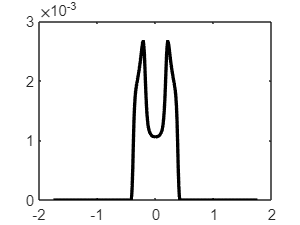

hold on
p1.LineWidth=2;
p2.LineWidth=2;



ylim([0 0.005])
xlim([-0.7 0.7])

ylabel 'Colony height [cm]'
xlabel 'Distance from the center [cm]'
%xticks([-2 -1 0 1 2])
%xticklabels({'2','1','0','1','2'})
ax=gca

ax =   Axes with properties:

             XLim: [-0.7000 0.7000]
             YLim: [0 0.0050]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.FontSize=20

ax =   Axes with properties:

             XLim: [-0.7000 0.7000]
             YLim: [0 0.0050]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1894 0.7750 0.7128]
            Units: 'normalized'

  Show all properties


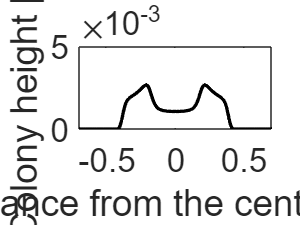

%legend('C_n=1[M] time=20h','C_n=0.1[M] time=100h','C_n=0.01[M] time=500h','C_n=0.001[M] time=2000h')
hold on